# 未知周期干扰的主动悬架鲁棒性与性能分析（Jafari, Ioannou,et al. 2015）

## 1 被控系统建模

考虑以下三阶模型：$G_0(z) = \frac{-0.00146(z - 0.1438)(z - 1)}{(z - 0.7096)(z^2 - 0.04369z + 0.01392)}$

离线设计控制器理论上能够完全拒绝干扰的周期性部分：

-  $d_s$ 是幅度为1的单频正弦信号，$v$ 是均值为零、标准差为0.02且 $|v| \leq 0.1$ 的高斯噪声。

- 采样周期 $T_s = 1/480 \text{sec}
$

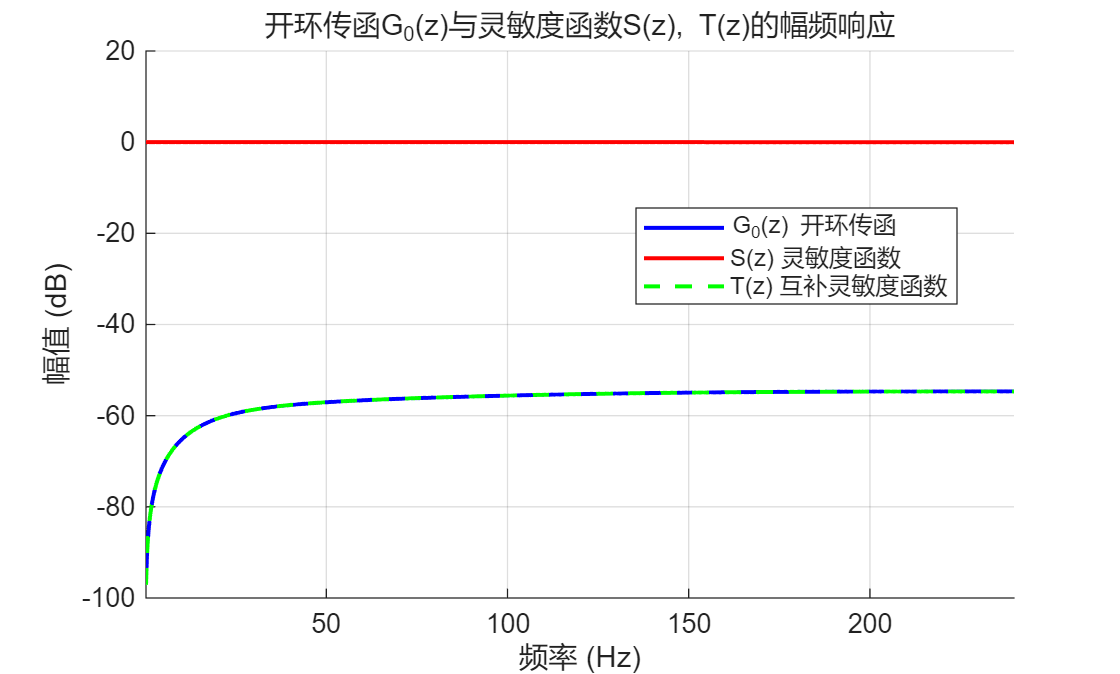

clear; close all; clc;
% 离散系统G0(z)
Ts = 1/480;
z = tf('z');
fs = 1/Ts;
G0 = (-0.00146*(z-0.1438)*(z-1)) / ((z - 0.7096)*(z^2 - 0.04369*z + 0.01392));

% 计算灵敏度函数和互补灵敏度函数
% 假设单位反馈: S = 1/(1+G0), T = G0/(1+G0)
S = feedback(1, G0);  % 灵敏度函数 S = 1/(1+G0)
T = feedback(G0, 1);  % 互补灵敏度函数 T = G0/(1+G0)

% 计算频率响应
[H_G0, f_bode] = freqz(G0.num{1}, G0.den{1}, 1000, fs);
[H_S, ~] = freqz(S.num{1}, S.den{1}, 1000, fs);
[H_T, ~] = freqz(T.num{1}, T.den{1}, 1000, fs);

% 绘制三个传递函数的幅频响应
figure; hold on; 
semilogx(f_bode, 20*log10(abs(H_G0)), 'b-', 'LineWidth', 1.5, 'DisplayName', 'G_0(z) 开环传函');
semilogx(f_bode, 20*log10(abs(H_S)), 'r-', 'LineWidth', 1.5, 'DisplayName', 'S(z) 灵敏度函数');
semilogx(f_bode, 20*log10(abs(H_T)), 'g--', 'LineWidth', 1.5, 'DisplayName', 'T(z) 互补灵敏度函数');
xlabel('频率 (Hz)');
ylabel('幅值 (dB)');
title('开环传函G_0(z)与灵敏度函数S(z), T(z)的幅频响应');
legend('Location', 'best'); grid on;
xlim([f_bode(2), f_bode(end)]); % 避免DC点的显示问题

## 2 求解准备

w_interp = [0.0521]; % interpolation frequencies (rad)
N = 15;
nf = length(w_interp);
z_interp = exp(1j * w_interp);

% frequency grid for Hinf constraints
Nfreq = 1000;                     
w_grid = linspace(0, pi, Nfreq);
z_grid = exp(1j*w_grid);
% precompute frequency responses
G_grid = squeeze(freqresp(G0, w_grid)).';        % 1 x Nfreq complex -> transpose to Nfreq x 1
G_interp = squeeze(freqresp(G0, w_interp)).';   % N x 1 complex
% build Phi matrices
Phi_grid = zeros(Nfreq, N);
Phi_interp = zeros(nf, N);
for k = 1:N
    Phi_grid(:,k)   = z_grid .^ (k-N-1);
    Phi_interp(:,k) = z_interp .^ (k-N-1); % equivalent
end

% build interpolation A * theta = b (complex)
A = diag(G_interp) * Phi_interp; % size N x N (complex)
b = ones(size(G_interp));        % complex ones

% if theta real, convert to real linear eqns
Aeq = [ real(A); imag(A) ];
beq = [ real(b)'; imag(b)' ];

% ---------- 可行性检查（先看是否存在满足等式的 theta） ----------
feasible_flag = true;
% 线性可行性：是否有 theta s.t. Aeq * theta = beq
% 简单尝试解方程并测残差
if size(Aeq,1) == size(Aeq,2)
    theta_test = Aeq \ beq;
    resnorm = norm(Aeq*theta_test - beq);
else
    theta_test = Aeq \ beq; % least squares if over/under
    resnorm = norm(Aeq*theta_test - beq);
end
fprintf('线性可行性检验: 等式最小残差 = %.3e\n', resnorm);

线性可行性检验: 等式最小残差 = 1.353e-17


if resnorm > 1e-8
    warning('插值等式可能无法严格满足 (残差 %.3e). 若要强制满足，可考虑增大 N 或放宽约束。', resnorm);
    % 依使用场景，可视为不可行 or 允许松弛
end

## 3 求解过程

### （1）最小二乘法求解优化问题

% ---------- 最小二乘基准解（仅供对比） ----------
theta_ls = theta_test;  % 使用前面计算的最小二乘解
fprintf('LS解的插值残差: %.3e\n', resnorm);

LS解的插值残差: 1.353e-17



% 计算最小二乘解的H∞性能
mag_ls = abs(G_grid(:) .* (Phi_grid * theta_ls));
gamma_ls = max(mag_ls);
fprintf('LS解的H∞范数: %.6f\n', gamma_ls);

LS解的H∞范数: 20.249837


fprintf('LS解的参数范数: %.6f\n', norm(theta_ls));

LS解的参数范数: 7961.720042


### （2）cvx求解优化问题

% ---------- CVX: 直接最小化 gammma，等式作为硬约束 ----------
if exist('cvx_begin','file') ~= 2
    error('CVX 未找到，请先安装并设置路径 (http://cvxr.com/cvx/)。');
end
r0 = 1e4;                     % theta norm bound (large if none)
cvx_begin quiet
    cvx_precision high
    variable theta(N,1)
    variable gammma nonnegative
    minimize( gammma )
    subject to
        for i = 1:Nfreq
            abs( G_grid(i) * (Phi_grid(i,:) * theta) ) <= gammma;
        end
        Aeq * theta == beq;
        norm(theta,2) <= r0;
cvx_end

### （3）最优化问题总结分析

theta_opt = theta;
compare_CVX_LS(gamma_ls, theta_ls, resnorm, gammma, theta_opt, Aeq, beq);


--- CVX vs 最小二乘解法对比 ---
方法          | H∞范数    | 参数范数   | 插值残差
-------------|----------|----------|----------
最小二乘(LS) | 20.249837 | 7961.720042 | 1.353e-17
CVX优化     | 10.425948 | 5132.792534 | 2.221e-16

CVX相对LS的H∞性能改善: 1.94倍
✓ CVX优化显著改善了H∞性能


% dense check validation
Mchk = 3000;
w_chk = linspace(0, pi, Mchk);
G_chk = squeeze(freqresp(G0, w_chk)).';
Phi_chk = zeros(Mchk, N);
for k=1:N, Phi_chk(:,k) = exp(-1j*w_chk*(k-1)); end
mag = abs( G_chk(:) .* (Phi_chk * theta_opt) );
gammma_check = max(mag);
fprintf('CVX gammma = %.6e, dense-grid gammma_check = %.6e, residual ||A theta - b|| = %.3e\n', gammma, gammma_check, norm(A*theta_opt - b));

CVX gammma = 1.042595e+01, dense-grid gammma_check = 1.042646e+01, residual ||A theta - b|| = 4.441e-16


## 4 抗干扰仿真分析

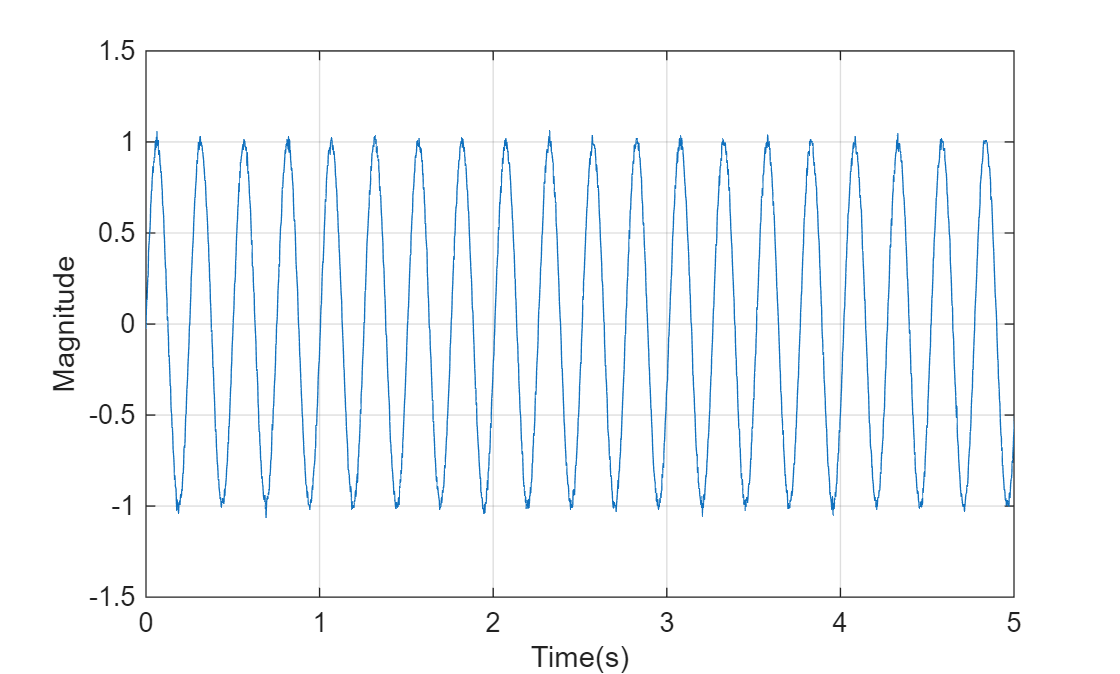

% 扰动参数
Ts = 1/480;
fs = 1/Ts;
omega0 = w_interp(:); % rad/sample, 25rad/sec
Nsim = 480*50;   % 50秒
t = (0:Nsim-1)*Ts;
d = sum(sin(omega0*t*fs) + 0.02*randn(length(omega0),Nsim),1);
figure('Name', '扰动信号');
plot(t, d); grid on;
xlabel('Time(s)'); ylabel('Magnitude');
xlim([0,5]);

% 构造 FIR 系数（z^-1 顺序）
b_K_cvx = [0; flip(theta_opt(:))]; % CVX优化解
b_K_ls = [0; flip(theta_ls(:))];   % 最小二乘解

% 绘制频率响应对比
nfft = 1024;
[Hk_cvx, fk] = freqz(b_K_cvx, 1, nfft, fs);
[Hk_ls, ~] = freqz(b_K_ls, 1, nfft, fs);

figure('Name', '控制器频率响应对比: CVX vs 最小二乘');
subplot(2,1,1); 
semilogx(fk, 20*log10(abs(Hk_cvx)), 'r-', 'LineWidth', 2, 'DisplayName', 'CVX优化解');
hold on;
semilogx(fk, 20*log10(abs(Hk_ls)), 'b--', 'LineWidth', 2, 'DisplayName', '最小二乘解');
xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); grid on;
title('控制器幅频响应对比');
legend('Location', 'best');
subplot(2,1,2); 
semilogx(fk, angle(Hk_cvx)*180/pi, 'r-', 'LineWidth', 2, 'DisplayName', 'CVX优化解');
hold on;
semilogx(fk, angle(Hk_ls)*180/pi, 'b--', 'LineWidth', 2, 'DisplayName', '最小二乘解');
xlabel('Frequency (Hz)'); ylabel('Phase (deg)'); grid on;
title('控制器相频响应对比');
legend('Location', 'best');
% 构造K(z,theta)
% Kz = tf(theta', [1 zeros(1,N-1)], Ts); % 可选
% 闭环仿真 - CVX解
u_cvx = zeros(1,Nsim);
y_cvx = zeros(1,Nsim);
x_cvx = zeros(1,Nsim);
antinoise_cvx = zeros(1,Nsim);

% 闭环仿真 - LS解
u_ls = zeros(1,Nsim);
y_ls = zeros(1,Nsim);
x_ls = zeros(1,Nsim);
antinoise_ls = zeros(1,Nsim);

% 获取G0(z)分子分母系数（z形式）
b = G0.num{1};
a = G0.den{1};

% 控制器仿真
for k = max(N,length(a))+1:Nsim
    if t(k) >= 20
        u_cvx(k) = -sum(theta_opt'.*x_cvx(k-(N:-1:1)));
        u_ls(k) = -sum(theta_ls'.*x_ls(k-(N:-1:1)));
        if(isnan(u_cvx(k))||isnan(u_ls(k)))
            pause;
        end
    end
    % 离散系统差分方程递推y(k)
    antinoise_cvx(k) = (-a(2:end)*antinoise_cvx(k-1:-1:k-length(a)+1)' + b*u_cvx(k-1:-1:k-length(b))')/a(1);
    antinoise_ls(k) = (-a(2:end)*antinoise_ls(k-1:-1:k-length(a)+1)' + b*u_ls(k-1:-1:k-length(b))')/a(1);
    y_cvx(k) = antinoise_cvx(k) + d(k);
    y_ls(k) = antinoise_ls(k) + d(k);
    x_cvx(k) = y_cvx(k) - antinoise_cvx(k);
    x_ls(k) = y_ls(k) - antinoise_ls(k);
end

% 绘图对比
figure('Name', '控制输入与输出信号对比');

subplot(2,1,1);
plot(t, u_cvx, 'r-', 'LineWidth', 1.5, 'DisplayName', 'CVX控制输入');
hold on;
plot(t, u_ls, 'b--', 'LineWidth', 1.5, 'DisplayName', 'LS控制输入');
xline(20, 'k:', 'Controller ON','HandleVisibility','off');
xlabel('Time (s)'); ylabel('Control Input u');
title('控制输入信号对比');
legend show; grid on;
subplot(2,1,2);
plot(t, d, 'k:', 'LineWidth', 1.0, 'DisplayName', 'Disturbance');
hold on;
plot(t, y_cvx, 'r-', 'LineWidth', 1.5, 'DisplayName', ['CVX (γ=' num2str(gammma, '%.3f') ')']);
plot(t, y_ls, 'b--', 'LineWidth', 1.5, 'DisplayName', ['LS (γ=' num2str(gamma_ls(end), '%.3f') ')']);
xline(20, 'k--', 'Controller ON','HandleVisibility','off');
xlabel('Time (s)');
ylabel('Plant output y');
title('闭环输出性能对比: CVX优化 vs 最小二乘');
legend show; grid on; ylim([-2,2]);

## 5 自适应仿真分析

% ---------- 1. 定义自适应滤波器F(z) ----------
% Jafari2015论文中没有明确指定F(z)，这里我们使用一个简单的二阶低通滤波器
% 这与Jafari_discrete.m中的简化思想一致
F = tf(1, 1, Ts);
b_F = 1;
a_F = 1;

% ---------- 2. 初始化自适应仿真变量 ----------
% 关键信号
kz_adapt = zeros(1,Nsim);
antinoise_term = zeros(1,Nsim);
u_adapt = zeros(1,Nsim);
y_adapt = zeros(1,Nsim);
z_adapt = zeros(1,Nsim); % 观测信号 z = y - G0*u
phi_adapt = zeros(N,1);    % 回归向量

% 自适应参数
theta_adapt = zeros(N,1); % 参数初值为0
P = eye(N) * 500;         % 协方差矩阵 (初始值较大)
gamma0 = 1.0;             % 归一化增益

% 历史缓冲区 (用于IIR滤波器)
hist_len = max([length(a), length(b)]) + N + 1;
G0_u_hist = zeros(1, length(b));
G0_y_hist = zeros(1, length(a));
% 为回归向量的每个元素创建独立的滤波器历史
phi_G0_u_hist = zeros(1, length(b));
phi_G0_y_hist = zeros(1, length(a));
phi_N = zeros(1, Nsim); % 监控 phi_N(k) = G0*z(k)
F_u_hist = zeros(1, length(b_F));
F_y_hist = zeros(1, length(a_F));

% 监控变量
theta_history = zeros(N, Nsim);
rms_history = zeros(1, Nsim);


--- 开始Jafari2015结构自适应仿真 ---


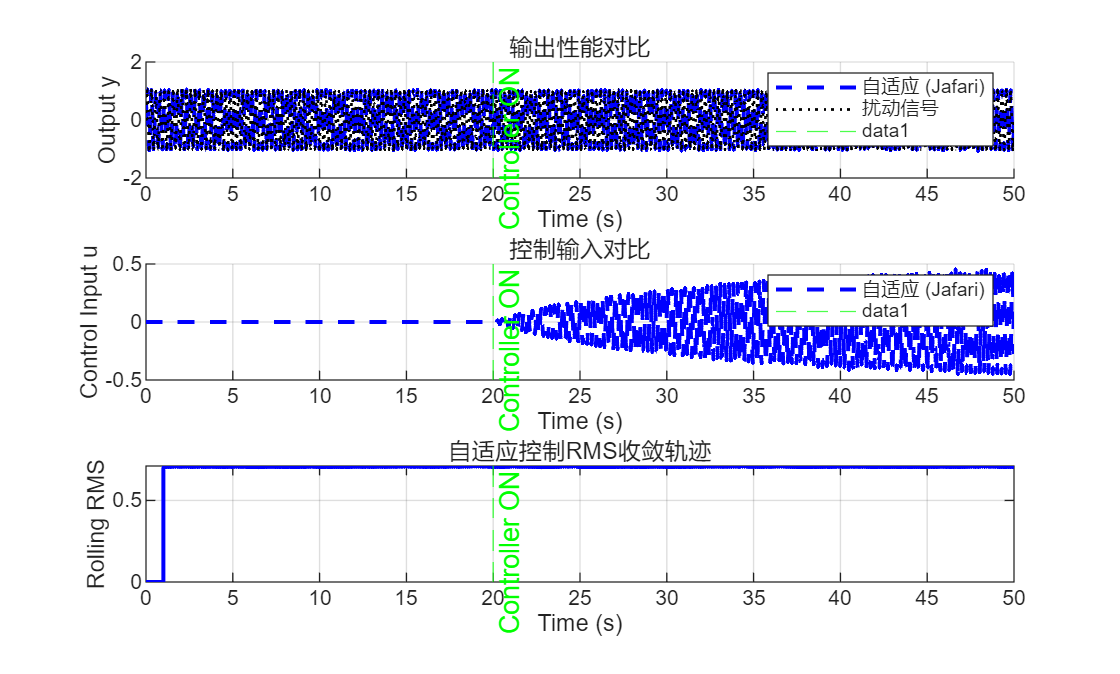


% ---------- 3. 自适应控制仿真循环 ----------
% phi_adpat   N×1
% theta_adpat N×1
for k = hist_len:Nsim
    % --- 步骤1: 计算系统输出 y(k) ---
    % y(k) = G(u(k-1)) + d(k)，这里假设 G=G0
    % 使用差分方程直接计算
    antinoise_term(k) = (-a(2:end)*antinoise_term(k-1:-1:k-length(a)+1)' + b*u_adapt(k-1:-1:k-length(b))')/a(1);
    y_adapt(k) = antinoise_term(k) + d(k);
    
    if t(k) >= 20  % 20秒后开启自适应控制
        % --- 步骤2: 计算观测信号 z(k) ---
        % z(k) = y(k) - G0(u(k-1))
        % G0(u(k-1))与上面计算的antinoise_term是同一个值
        z_adapt(k) = y_adapt(k) - antinoise_term(k);

        % --- 步骤3: 计算回归向量 phi(k) ---
        % phi_i(k) = G0 * F * z(k-i)
        [phi_N(k), phi_G0_u_hist, phi_G0_y_hist] = IIR_filter(b, a, z_adapt(k), phi_G0_u_hist, phi_G0_y_hist);
        phi_adapt = phi_N(k-(N:-1:1))'; % 取最近N个值构成回归向量

        % --- 步骤4: 更新自适应参数 theta(k) ---
        % 归一化RLS算法 (Normalized RLS)
        m_s_squared = 1 + gamma0 * (phi_adapt' * phi_adapt);
        prediction_error = z_adapt(k) - theta_adapt' * phi_adapt;
        epsilon = prediction_error / m_s_squared;
        
        % 协方差矩阵 P 和 增益 K 的更新
        P_phi = P * phi_adapt;
        denom = m_s_squared + phi_adapt' * P_phi;
        K = P_phi / denom; % 增益向量
        P = P - (K * P_phi');
        theta_adapt = theta_adapt + P * phi_adapt * epsilon; % 使用未归一化的误差

        % --- 步骤5: 计算控制信号 u(k) ---
        % u(k) = -F * (theta(k)' * phi(k))
        K_z_k = theta_adapt' * phi_adapt;
        kz_adapt(k) = -K_z_k;
        [u_adapt(k), F_u_hist, F_y_hist] = IIR_filter(b_F, a_F, -K_z_k, F_u_hist, F_y_hist);
    else
        % 控制器关闭时，系统自由响应
        z_adapt(k) = y_adapt(k); % z=y
        u_adapt(k) = 0;
    end
    
    % 记录历史数据
    theta_history(:,k) = theta_adapt;
    if k > fs
        window_start = max(1, k - fs + 1);
        rms_history(k) = rms(y_adapt(window_start:k));
    end
end

% ---------- 4. 性能分析与可视化 ----------
% 自适应控制性能对比
figure('Name', '自适应(Jafari结构) vs 固定MOSEK控制器');
subplot(3,1,1);
hold on;
plot(t, y_adapt, 'b', 'LineWidth', 1.5, 'DisplayName', '自适应 (Jafari)');
plot(t, d, 'k:', 'LineWidth', 1.0, 'DisplayName', '扰动信号');
xline(20, 'g--', 'Controller ON');
xlabel('Time (s)'); ylabel('Output y');
title('输出性能对比');
legend show; grid on; ylim([-2,2]);

subplot(3,1,2);
hold on;
plot(t, u_adapt, 'b--', 'LineWidth', 1.5, 'DisplayName', '自适应 (Jafari)');
xline(20, 'g--', 'Controller ON');
xlabel('Time (s)'); ylabel('Control Input u');
title('控制输入对比');
legend show; grid on;

subplot(3,1,3);
plot(t, rms_history, 'b-', 'LineWidth', 1.5);
xline(20, 'g--', 'Controller ON');
xlabel('Time (s)'); ylabel('Rolling RMS');
title('自适应控制RMS收敛轨迹');
grid on;

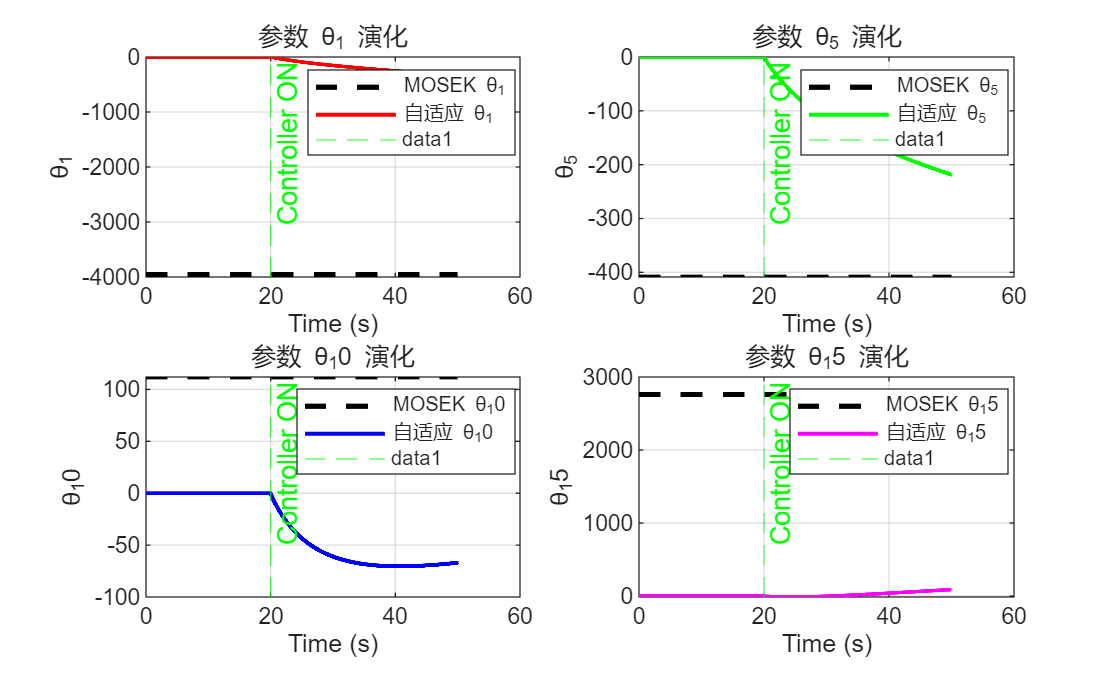


% 参数演化对比
figure('Name', '控制器参数演化对比: MOSEK vs 自适应(Jafari)');
param_indices = [1, 5, 10, 15];
colors = {'r-', 'g-', 'b-', 'm-'};
for i = 1:length(param_indices)
    subplot(2,2,i);
    idx = param_indices(i);
    plot(t, repmat(theta_opt(idx), 1, Nsim), 'k--', 'LineWidth', 2, 'DisplayName', sprintf('MOSEK θ_%d', idx));
    hold on;
    plot(t, theta_history(idx,:), colors{i}, 'LineWidth', 1.5, 'DisplayName', sprintf('自适应 θ_%d', idx));
    xline(20, 'g--', 'Controller ON', 'Alpha', 0.7);
    xlabel('Time (s)'); ylabel(sprintf('θ_%d', idx));
    title(sprintf('参数 θ_%d 演化', idx));
    legend('Location', 'best'); grid on;
end

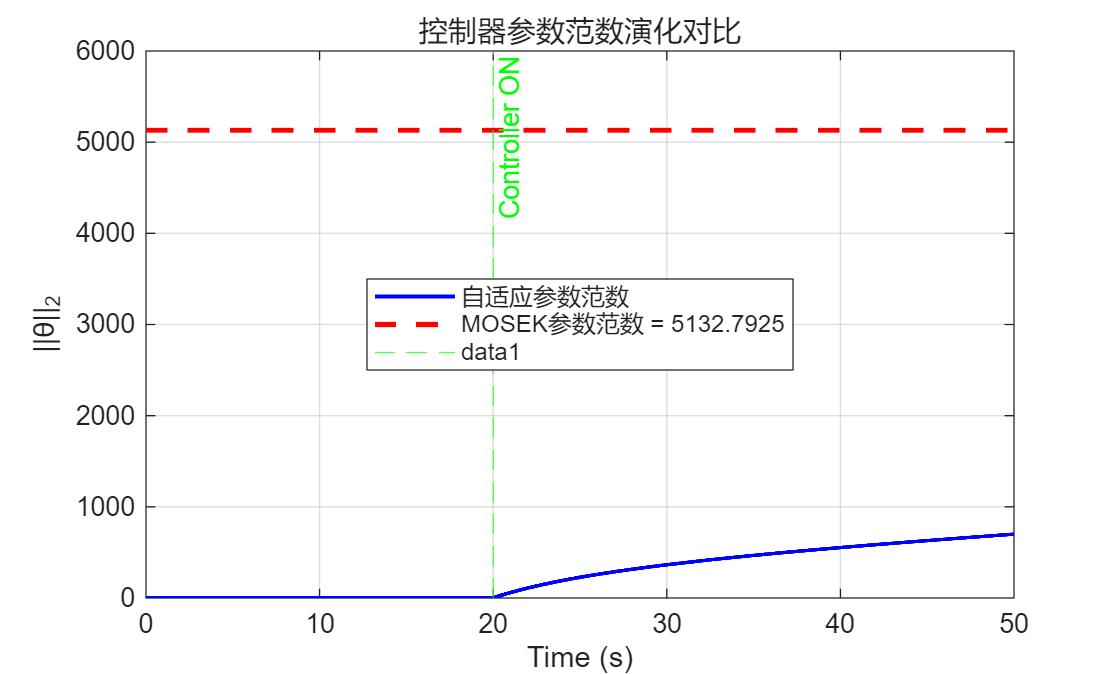


% 所有参数的范数演化
figure('Name', '控制器参数范数演化 (Jafari)');
theta_norm_history = sqrt(sum(theta_history.^2, 1));
plot(t, theta_norm_history, 'b-', 'LineWidth', 1.5, 'DisplayName', '自适应参数范数');
hold on;
plot(t, repmat(norm(theta_opt), 1, Nsim), 'r--', 'LineWidth', 2, ...
     'DisplayName', sprintf('MOSEK参数范数 = %.4f', norm(theta_opt)));
xline(20, 'g--', 'Controller ON');
xlabel('Time (s)'); 
ylabel('||θ||_2');
title('控制器参数范数演化对比');
legend('Location', 'best'); 
grid on;

## 附录

function compare_CVX_LS(gamma_ls, theta_ls, resnorm, gammma, theta_opt, Aeq, beq)
    fprintf('\n--- CVX vs 最小二乘解法对比 ---\n');
    fprintf('方法          | H∞范数    | 参数范数   | 插值残差\n');
    fprintf('-------------|----------|----------|----------\n');
    fprintf('最小二乘(LS) | %.6f | %.6f | %.3e\n', gamma_ls, norm(theta_ls), resnorm);
    fprintf('CVX优化     | %.6f | %.6f | %.3e\n', gammma, norm(theta_opt), norm(Aeq*theta_opt - beq));

    % 性能改善分析
    improvement_ratio = gamma_ls / gammma;
    fprintf('\nCVX相对LS的H∞性能改善: %.2f倍\n', improvement_ratio);
    if improvement_ratio > 1.2
        fprintf('✓ CVX优化显著改善了H∞性能\n');
    elseif improvement_ratio > 1.05
        fprintf('△ CVX优化略有改善H∞性能\n'); 
    else
        fprintf('○ CVX与LS性能接近，可能H∞约束不起作用\n');
    end
end